Aluminum data source:

[https://asm.matweb.com/search/specificmaterial.asp?bassnum=ma6061t6](https://asm.matweb.com/search/specificmaterial.asp?bassnum=ma6061t6)

## General Variables

% oldpath = path
% path(path);
clear;

P_c         = 30*10^5; %     Pa    Chamber pressure
P_i         = 55*10^5; %     Pa    Injector pressure
OD_s        = 4*2.54/100; % m    Outer diameter of chamber shell
T_s         = 0.125*2.54/100; % m    Thickness of chamber shell
ID_s        = OD_s - 2*T_s;
D_t         = 1.24*2.54/100; % m    Throat diameter

aluminumBearing = 386; % MPa        Bearing strength of aluminum 6061
aluminumShear   = 207; % MPa        Shear strength of aluminum 6061
aluminumYield   = 276; % MPa        Yield strength of aluminum 6061

boltTensile = 827;
boltShear   = boltTensile*.58; % This approximation for shear stress is generally available online

phenolicShear = 130; % MPa

steelShear = 415*.6; % MPa

graphiteShear   = 0; % MPa          Graphite shear strength

## Hoop Stress

## 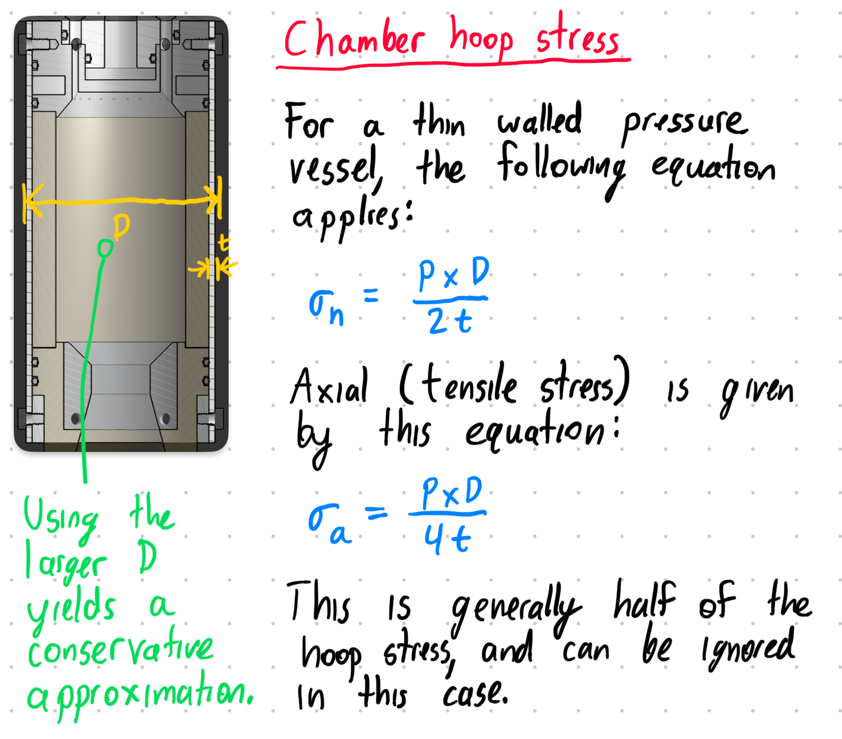

hoopCalc.P = P_c;
hoopCalc.d = OD_s;
hoopCalc.t = T_s;

hoopStress = getHoopStress(hoopCalc)/10^6;

showFOS('Chamber hoop stress', aluminumYield, hoopStress);

Chamber hoop stress       	Stress: 48.0 MPa 	FOS: 5.75

## Lower Bolts

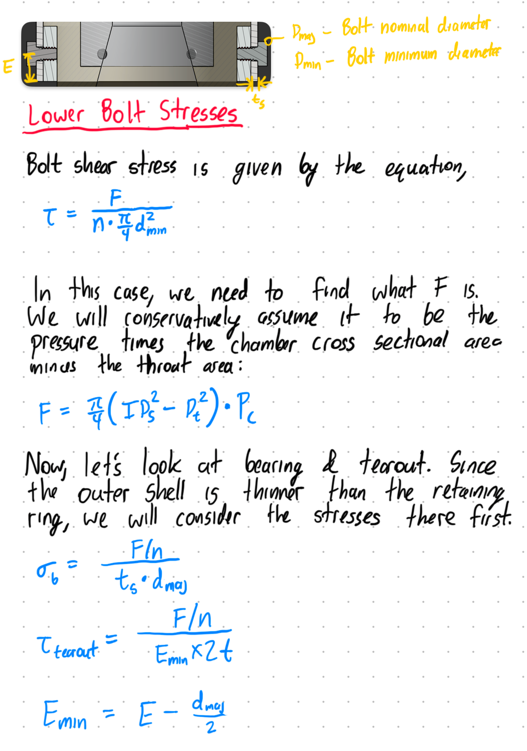

Major diameter of the bolt is the diameter at the outside of the threads.

Minor diameter of the bolt is the diameter at the inside of the threads.

lowerbolts.d_maj = 0.25*2.54/100; % m     Major diameter of bolt shaft
lowerbolts.d_min = 0.1887*2.54/100; % m     Major diameter of bolt shaft
lowerbolts.n     = 6; %          -     Number of bolts
lowerbolts.E     = 0.5*2.54/100; % m     Casing tear out distance
lowerbolts.t     = T_s; %                           m     Thickness of wall
lowerbolts.F     = pi/4*(ID_s^2 - D_t^2)*P_c; %     N     Conservative estimate for force on nozzle

boltShearStress = getBoltShearStress(lowerbolts)/10^6;
shellTearOut    = getBoltTearOutStress(lowerbolts)/10^6;
bearingStress   = getBoltBearingStress(lowerbolts)/10^6;

showFOS("Lower bolt shear", boltShear, boltShearStress);

Lower bolt shear          	Stress: 175.9 MPa 	FOS: 2.73

showFOS("Lower shell tear out", aluminumShear, shellTearOut);

Lower shell tear out      	Stress: 52.5 MPa 	FOS: 3.95

showFOS("Lower casing bearing", aluminumBearing, bearingStress);

Lower casing bearing      	Stress: 157.4 MPa 	FOS: 2.45

## Upper Bolts

The upper bolt analysis is identical to the lower bolts case, except that the pressure is applied over the entire face which increases the force pushing on the bolts.

upperbolts.d_maj = 0.25*2.54/100; % m     Major diameter of bolt shaft
upperbolts.d_min = 0.1887*2.54/100; % m     Major diameter of bolt shaft
upperbolts.n     = 6; %          -     Number of bolts
upperbolts.E     = 0.5*2.54/100; % m     Casing tear out distance
upperbolts.t     = T_s; %                           m     Thickness of wall
upperbolts.F     = pi/4*ID_s^2*P_c; %               N     Force on injector

boltShearStress = getBoltShearStress(upperbolts)/10^6;
shellTearOut    = getBoltTearOutStress(upperbolts)/10^6;
bearingStress   = getBoltBearingStress(upperbolts)/10^6;

showFOS("Upper bolt shear", boltShear, boltShearStress);

Upper bolt shear          	Stress: 197.5 MPa 	FOS: 2.43

showFOS("Upper shell tear out", aluminumShear, shellTearOut);

Upper shell tear out      	Stress: 58.9 MPa 	FOS: 3.51

showFOS("Upper casing bearing", aluminumBearing, bearingStress);

Upper casing bearing      	Stress: 176.7 MPa 	FOS: 2.18

## Nozzle Insert

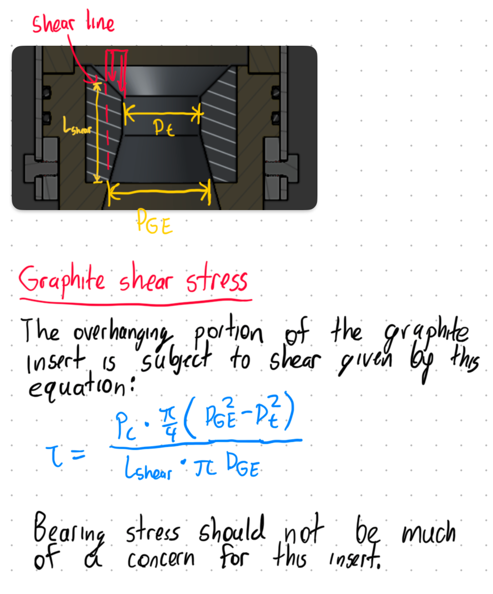

The graphite shear stress only requires the pressure force to be calculated using the overhanging portion of the nozzle. The bearing stress requires using the forces on the whole graphite piece. Once again, we will assume that all of the pressures on the chamber side equal chamber pressure and that the pressure on the other size is zero, which is a conservative assumption.

graphite.D_shear   = 1.648*2.54/100; % m     Graphite shear diameter
graphite.L_shear   = 1.853*2.54/100; % m     Graphite shear length
graphite.F_shear   = P_c*.25*pi*(graphite.D_shear^2 - D_t^2); %   Graphite shear force

cylinderShear = getCylinderShearStress(graphite)/10^6;

showFOS("Graphite shear", graphiteShear, cylinderShear); 

Graphite shear            	Stress: 0.3 MPa 	FOS: 0.00

## Nozzle Carrier

## 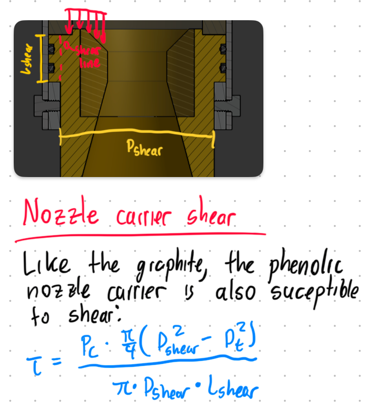

carrier.D_shear   = 2.747*2.54/100; % m             Nozzle carrier shear diameter
carrier.L_shear   = 1*2.54/100; % m             Nozzle carrier shear length
carrier.F_shear   = P_c*.25*pi*(carrier.D_shear^2 - D_t^2); %  N   Nozzle carrier shear force

cylinderShear = getCylinderShearStress(carrier)/10^6;

showFOS("Nozzle carrier shear", phenolicShear, cylinderShear); 

Nozzle carrier shear      	Stress: 1.6 MPa 	FOS: 79.25

## Axial Bolts

- Normal stress

- Pulling out of threads

- Bearing stress on bolt heads

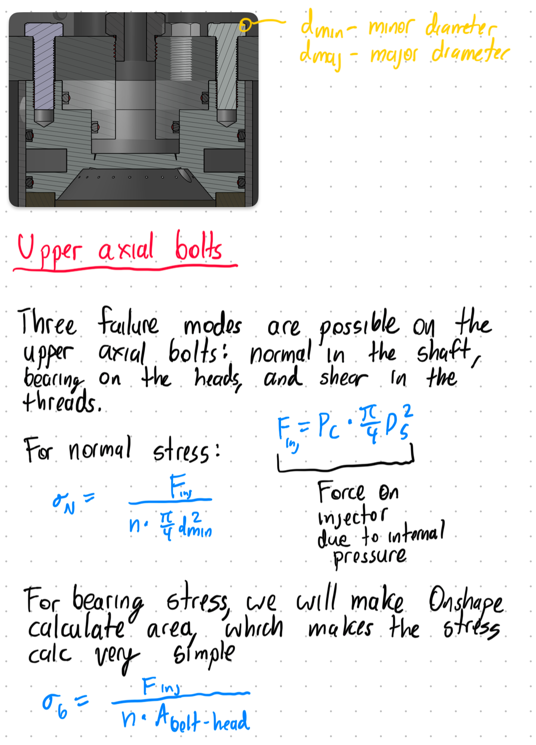

axial.n      = 5;
axial.D_ox   = 1.5*2.54/100;
axial.A_head = 0.111*(2.54/100)^2;
axial.d_min  = 0.3239*2.54/100;
axial.F      = 4*P_i*.25*axial.D_ox^2;


normalStress = axial.F/(axial.n*pi/4*axial.d_min^2)/10^6;
bearingStress = axial.F/(axial.n*axial.A_head)/10^6;

showFOS('Axial bolt tension', boltTensile, normalStress);

Axial bolt tension        	Stress: 30.0 MPa 	FOS: 27.53

showFOS('Bearing stress', aluminumBearing, bearingStress);

Bearing stress            	Stress: 22.3 MPa 	FOS: 17.31

## Injector face

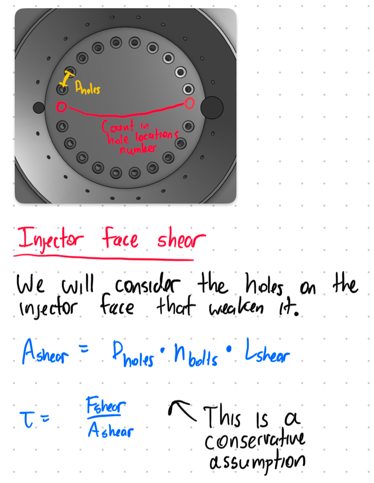

injector.holeDistance = 0.207*2.54/100;
injector.N_holes      = 22;
injector.L_shear      = 0.264*2.54/100;
injector.A_shear      = injector.holeDistance*injector.N_holes*injector.L_shear;
injector.F_shear      = axial.F;

injectorShear = injector.F_shear/injector.A_shear/10^6;

showFOS('Injector shear', steelShear, injectorShear);

Injector shear            	Stress: 10.3 MPa 	FOS: 24.19

## Connection bolts

This is just another simple bolt loading case, so the math is included but not written out.

We're looking at these:

- Bolt shear 

- Bearing failure

connection.d_maj = 0.25*2.54/100; % m     Major diameter of bolt shaft
connection.d_min = 0.1887*2.54/100; % m     Major diameter of bolt shaft
connection.t     = 0.125*2.54/100; % m     Thickness of wall
connection.n     = 8; %          -     Number of bolts
connection.F     = 3336; %          N     Thrust estimate

boltShearStress = getBoltShearStress(connection)/10^6;
bearingStress   = getBoltBearingStress(connection)/10^6;

showFOS("Lower bolt shear", boltShear, boltShearStress);

Lower bolt shear          	Stress: 23.1 MPa 	FOS: 20.75

showFOS("Lower casing bearing", aluminumBearing, bearingStress);

Lower casing bearing      	Stress: 20.7 MPa 	FOS: 18.66